% Model_8_50
% Define parameters
k = 2.667;    % Value of 'k'
tau = 1331.4;    % Value of 'tau'

% Define control input function (example: step function)
u = @(t) 1 * (t >= 1);  % Step function at t = 1

% Define the differential equation function
f1 = @(t, x) -1/tau *(x-xr) + k/tau * u(t);

% Initial condition
xr = 100;   % Reference value
x0 = 210;   % Initial value of x

% Time span
tspan = 0:15:10000;

% Solve the differential equation
[~, x1] = ode45(f1, tspan, xr);

% MRAC Control
% Define system parameters
k = 2.667;    % Value of 'k'
tau = 1331.4;    % Value of 'tau'

% Parameters
am = 0.0015; % Reference model parameter
bm = 0.001;   % Reference model parameter
a = 1/tau;   % Plant parameter
b = k/tau;   % Plant parameter
gamma = 1e-06; % Adaptation rate

% Control gains
kx = (am - a)/b

kx = 0.3739

kr = bm/b

kr = 0.4992

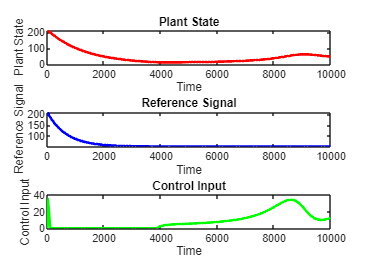


% Simulation parameters
dt = 15; % Time step
t_end = 10000; % Simulation time

% Reference signal
t = 0:dt:t_end;

% Define the differential equation function for reference model
x_hat = 210;
f = @(t, xm) -am * (xm - 50) + bm;

% Solve the differential equation for reference model
[~, xm] = ode45(f, t, x_hat);
r = xm;

% Initialize variables
x = zeros(size(t));  % Plant state
x(1) = 210; % initial condition
theta = zeros(size(t));  % Parameter estimate
theta(1) = 0.7; % initial guess
u = zeros(size(t));  % Control input
error = zeros(size(t));  % Control input

% Main loop
for i = 2:length(t)
    % Error
    e = r(i) - x(i-1);
    error(i) = e;
    
    % Control law
    u(i) = kx * x(i-1) + kr * r(i) - theta(i-1) * x(i-1);

    % Limit control input to the range [0, 100]
    u(i) = min(max(u(i), 0), 100);
    
    % Update plant state
    x(i) = x(i-1) + dt * (-a * x(i-1) + b * u(i));
    
    % Adaptation law
    theta_dot = -gamma * e * x(i-1);
    theta(i) = theta(i-1) + dt * theta_dot;
end

% Plot results
figure;
subplot(3,1,1);
plot(t, x, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Plant State');
title('Plant State');

subplot(3,1,2);
plot(t, r, 'b', 'LineWidth', 2);
xlabel('Time');
ylabel('Reference Signal');
title('Reference Signal');

subplot(3,1,3);
plot(t, u, 'g', 'LineWidth', 2);
xlabel('Time');
ylabel('Control Input');
title('Control Input');

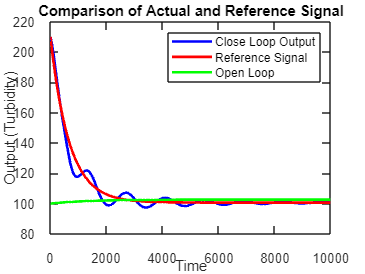


% Plot results
figure;
plot(t, x, 'b', t, r, 'r','LineWidth', 2);
hold on
plot(t,x1,'g','LineWidth', 2)
hold off
xlabel('Time');
ylabel('Output (Turbidity)');
legend('Close Loop Output', 'Reference Signal','Open Loop');
title('Comparison of Actual and Reference Signal');


subplot(3,1,1)

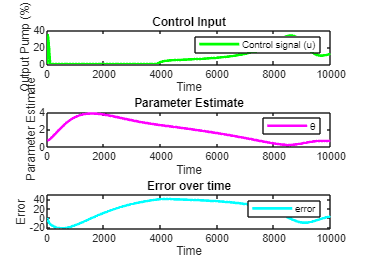

plot(t,u, 'g', 'LineWidth', 2);
xlabel('Time');
legend('Control signal (u)')
ylabel('Output Pump (%)');
title('Control Input');

subplot(3,1,2)
plot(t, theta, 'm', 'LineWidth', 2);
xlabel('Time');
legend('θ')
ylabel('Parameter Estimate');
title('Parameter Estimate');

subplot(3,1,3)
plot(t, error, 'c', 'LineWidth', 2);
xlabel('Time');
legend('error')
ylabel('Error');
title('Error over time');